clc; close all; clear;
addpath('inc\')
load("data\trajectory_jointSpace.mat")
load("data\system_parameters.mat");
load("data\circle_points.mat")



## Tip Position

o4 = zeros(3,length(qAB));
for i = 1:length(qAB)
    o4(:,i) = fwdKin(qAB(:,i),p).T40(1:3,4);
end

## Plotting

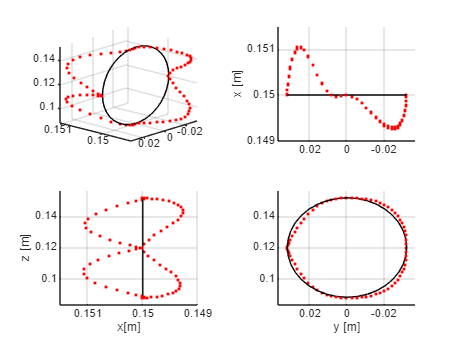

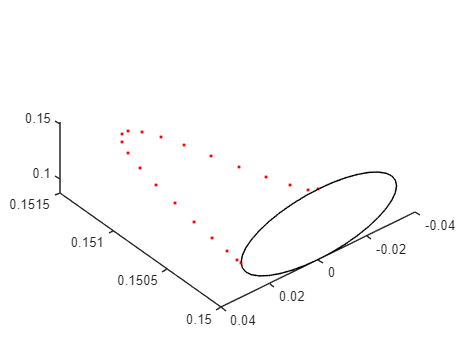

figure;
tiledlayout(2,2)
ax1 = nexttile;
hold on
plot3(o4(1,:),o4(2,:),o4(3,:),'.',Color='r')
plot3(point(1,:),point(2,:),point(3,:),'k')
view([222.740 19.787])
% axis square;
grid on
ax2 = nexttile;
hold on
plot3(o4(1,:),o4(2,:),o4(3,:),'.',Color='r')
plot3(point(1,:),point(2,:),point(3,:),'k')
view([-90 90]);
grid on
ax3 = nexttile;
hold on
plot3(o4(1,:),o4(2,:),o4(3,:),'.',Color='r')
plot3(point(1,:),point(2,:),point(3,:),'k')
view([-180 0]);
grid on
ax4 = nexttile;
hold on
plot3(o4(1,:),o4(2,:),o4(3,:),'.',Color='r')
plot3(point(1,:),point(2,:),point(3,:),'k')
% plot(o4(2,:),o4(3,:),'.',Color='r')
% plot(point(2,:),point(3,:),'k')
view([-90 0]);
grid on
% axis equal
linkaxes([ax2 ax3 ax4],'xyz')
ax4.ZLim = [0.083 0.157];
ax4.YLim = [-0.037 0.037];

nexttile(2)
xlabel("x [m]")
nexttile(3)
xlabel("x[m]")
zlabel("z [m]")
nexttile(4)
ylabel("y [m]")